# Supervised Learning - Week 2 / Part 1

In this part we will learn how to make linear regression algorithm much faster and powerful.

- Suppose we are interested in linear regression and we are looking for not only one feature but multiple features.

- In the previous part we saw that our dataset had one feature; $x$, size of the house, and we were predicting $y$; price of the house by using the linear regression formula: $y = wx+b$.

-  What if we not only know the size of the house ($x_1$) but also the number of bedrooms ($x_2$), number of floors ($x_3$) and age of the house in years ($x_4$)?

clear all;
close all;
clc;

% Table
hSize = [2104; 1416; 1534; 852];
hNumBedrooms = [5; 3; 3; 2];
hNumFloors = [1; 2; 2; 1];
hAge = [45; 40; 30; 36];
hPrice = [460; 232; 315; 178];
table(hSize,hNumBedrooms,hNumFloors,hAge,hPrice)

ans = 4×5 table
    hSize    hNumBedrooms    hNumFloors    hAge    hPrice
    _____    ____________    __________    ____    ______

    2104          5              1          45      460  
    1416          3              2          40      232  
    1534          3              2          30      315  
     852          2              1          36      178  


- Note that we represent each feature ($j^{\text{th}}$ column in the table) with subscript $j$, where $\mathbf{x}_j = [x^{(1)}_j ~ x^{(2)}_j ~ \cdots ~ x^{(m)}_j]^\text{T}$ $j^{\text{th}}$ feature, for $j \in \{1,2,\cdots,n\}$. 

- We represent the number of features by using $n$, where $n=4$ for the table above. 

- Moreover, $\mathbf{x}^{(i)} = [x_1 ~ x_2 ~ \cdots ~ x_n]$ represents the features of $i^{\text{th}}$ training example ($i^{\text{th}}$ row in the table), where $i \in \{1,2,\cdots,m\}$. The parameter $m$ represents the number of examples.

- Consequently, we can represent the value of $j^{\text{th}}$ feature (column) in $i^{\text{th}}$ training example (row) by using the notation $x_j^{(i)}$.

Now, we have multiple features, let's look at our how our model look like

- **Previously:    **$f_{w,b}(x) = wx + b$

- **If we generalize the one feature case:    **$f_{w,b}(\mathbf{x}) = w_1x_1+w_2x_2+\cdots+w_nx_n +b \\
= \left( \sum_{i=1}^{n}w_ix_i \right) +b = \mathbf{w}^{\text{T}} \mathbf{x} + b$

where this expression is called multi parameter linear regression. More importantly, here, both $\mathbf{w}$ and $b$ are the parameters.

Example: $f_{w,b}(\mathbf{x}) = \text{Price} = 0.1 \cdot \text{size} + 4 \cdot \text{numBedrooms} + 10 \cdot \text{numFloors} - 2\cdot \text{years} + \text{basePrice} $

- Base price of a house starts at $80 000 assuming it has no size, no bedrooms, no floors and no age.

- For every addtiional squared foot, the price increases $100.

- For every addition of bedrooms, the price increases $4000.

- For every addition of floors, the price increases $10 000.

- For every additional year in houses age, the price reduces $2000.

## Vectorization

We can define a case where $n = 3$


$$\mathbf{w} = [w_1 ~~ w_2 ~~ w_3]^{\text{T}}$$



$$\mathbf{x} = [x_1 ~~ x_2 ~~ x_3]^{\text{T}}$$


$b$ is a number

We can calculate the linear regression expression without vectorization as follows:

If the number of features is not 3 but 100 000, this would be inefficient to code as well as inefficient for the computation. An alternative approach without also vectorization becomes,

With vectorization,

or

**Let's evaluate the benefits of vectorization**

w = randn(1e8,1);
x = randn(1e8,1);

% Non-vectoral implementation
tStart = tic;
f = 0;
for i = 1:length(x)
    f = f + w(i)*x(i);
end
tExec = toc(tStart);
disp(['Non-vectoral execution time: ', num2str(tExec),' seconds.'])

Non-vectoral execution time: 0.17638 seconds.


% Vectoral implementation
tStart = tic;
f = w.'*x;
tExec = toc(tStart);
disp(['Vectoral implementation execution time: ', num2str(tExec),' seconds.'])

Vectoral implementation execution time: 0.096702 seconds.


clear w x % release memory

## Linear Regression with Multiple Variables

------------------------------

**                                            Single Varible (Scalar) Notation**

- **Inputs:                    **$x^{(i)}$

- **Labels:                   **$y^{(i)}$

- **Parameters:          **$w$ and $b$

- **Model:                    **$f_{w,b}(x^{(i)}) = wx^{(i)} + b$

- **Cost Function:      **$J(w,b) = \frac{1}{2m} \sum_{i=1}^{m} \left(  f_{w,b}(x^{(i)}) - y^{(i)}  \right)^2 = \frac{1}{2m} \sum_{i=1}^{m} \left(  wx^{(i)}+b - y^{(i)}  \right)^2$

- **Gradient Descent: **$w = w - \alpha\frac{\text{d} J(w,b)}{\text{d}w}$ and $b = b - \alpha\frac{\text{d} J(w,b)}{\text{d}b}$

------------------------------

**                                            Multiple Variables (Vector) Notation**

- **Inputs:                   **$\mathbf{x}^{(i)} = [x_1~ x_2~\cdots~x_n]$ represents the $i^{\text{th}}$ row of $\mathbf{X}$, where $\mathbf{X}$ is the $m\times n$ input data matrix.

- **Labels:**                  $y^{(i)}$

- **Parameters:          **$\mathbf{w} = [w_1~w_2~\cdots w_n]^{\text{T}}$ and $b$

- **Model:                    **$f_{\mathbf{w},b}(\mathbf{x}^{(i)}) = \mathbf{x}^{(i)}\mathbf{w}+ b = \left( \sum_{j=1}^{n}w_jx^{(i)}_j \right) + b$, for $i \in \{ 1,2,\cdots,m\}$ or $f_{\mathbf{w},b}(\mathbf{X}) = \mathbf{X}\mathbf{w} + b$

- **Cost Function:      **$J(\mathbf{w},b) = \frac{1}{2m}\sum_{i=1}^{m}\left(  \left(  \sum^{n}_{j=1} w_jx_j^{(i)} \right) + b - y^{(i)}\right)^2$ or $J(\mathbf{w},b) = \frac{1}{2m}\sum_{i=1}^{m} \left( \mathbf{x}^{(i)}\mathbf{w} + b - y^{(i)} \right)^2$

- **Gradient Descent: **$w_j = w_j - \alpha\frac{\partial}{\partial w_j}J(\mathbf{w},b)$, for $j \in \{ 1,2,\cdots, n\}$ and $b = b - \alpha\frac{\partial}{\partial b}J(\mathbf{w},b)$

------------------------------

How can we minimize the cost function in multiple variable case? 

- We can calculate the gradient of the cost function w.r.t. $\mathbf{w}$ as follows:

$\nabla J(\mathbf{w},b) = \left[
\begin{array}{c}
\frac{\partial J(\mathbf{w},b)}{\partial w_0}  \\
\frac{\partial J(\mathbf{w},b)}{\partial w_1}  \\
\vdots \\
\frac{\partial J(\mathbf{w},b)}{\partial w_n}
\end{array}
\right]$, where the parial derivative $\frac{\partial}{\partial w_j}J(\mathbf{w},b)$ for $j \in \{ 0,1,2,\cdots,n\}$ could be calculated as follows:

1) $\frac{\partial}{\partial w_j}J(\mathbf{w},b) = \frac{\partial}{\partial w_j} \left( \frac{1}{2m} \sum_{i=1}^{m}\left( \mathbf{x}^{(i)}\mathbf{w} +b - y^{(i)}\right)^2 \right) = \frac{1}{2m} \sum_{i=1}^{m} \frac{\partial}{\partial w_j} \left(  \left(  \sum^{n}_{j=1} w_jx_j^{(i)} \right) + b - y^{(i)}\right)^2$

2) By using the chain and sum rules,


$$\frac{\partial}{\partial w_j}J(\mathbf{w},b) = \frac{1}{m} \sum_{i=1}^{m} \left(  \left( \sum^{n}_{j=1} w_jx_j^{(i)} \right) + b - y^{(i)}\right) \left( \frac{\partial}{\partial w_j} \sum^{n}_{j=1} w_jx_j^{(i)} \right) \\
=  \frac{1}{m} \sum_{i=1}^{m} \left(  \left( \sum^{n}_{j=1} w_jx_j^{(i)} \right) + b - y^{(i)}\right) \left( \frac{\partial}{\partial w_j} \left(w_0x_0^{(i)} + w_1x_1^{(i)} + \cdots + w_nx_n^{(i)} \right)  \right) $$


3) We can see from the above expression that 

$\frac{\partial}{\partial w_j} \left(w_0x_0^{(i)} + w_1x_1^{(i)} + \cdots + w_nx_n^{(i)} \right) = x_j^{(i)}$ for $j \in \{ 0,1,2,\cdots,n \}$.

4) Therefore,


$$\frac{\partial}{\partial w_j}J(\mathbf{w},b) = \frac{1}{m} \sum_{i=1}^{m} \left(  w_1x_1^{(i)} + w_wx_w^{(i)} + \cdots w_nx_n^{(i)} + b - y^{(i)} \right) \cdot
x_j^{(i)} 
= \frac{1}{m}\sum_{i=1}^{m} \left( \mathbf{x}^{(i)} \mathbf{w} +b - y^{(i)} \right) \cdot
x_j^{(i)}$$


Similarly, the partial derivative of the cost function w.r.t. the bias becomes,

5) $\frac{\partial}{\partial b}J(\mathbf{w},b) = \frac{\partial}{\partial b}\left( \frac{1}{2m} \sum_{i=1}^{m}\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) - y^{(i)}\right)^2 \right) =\frac{1}{2m} \sum_{i=1}^{m}\frac{\partial}{\partial b}\left(  \left(  \sum^{n}_{j=1} w_jx_j^{(i)} \right) + b - y^{(i)}\right)^2$

6) If we solve the above expression using (2)


$$\frac{\partial}{\partial b}J(\mathbf{w},b) = \frac{1}{m} \sum_{i=1}^{m} \left(  w_1x_1^{(i)} + w_2x_2^{(i)} + \cdots w_nx_n^{(i)} + b - y^{(i)} \right) \cdot \frac{\partial}{\partial b} \left( w_1x_1^{(i)} + w_2x_2^{(i)} + \cdots w_nx_n^{(i)} + b - y^{(i)} \right)$$


7) As we know that $ \frac{\partial}{\partial b} \left( w_1x_1^{(i)} + w_2x_2^{(i)} + \cdots w_nx_n^{(i)} + b - y^{(i)} \right) = 1$. Hence,


$$\frac{\partial}{\partial b}J(\mathbf{w},b) =  \frac{1}{m} \sum_{i=1}^{m} \left( w_1x_1^{(i)} + w_2x_2^{(i)} + \cdots w_nx_n^{(i)} + b - y^{(i)} \right) = \frac{1}{m} \sum_{i=1}^{m} \left( \mathbf{x}^{(i)} \mathbf{w} + b - y^{(i)} \right)$$


------------------------------

**Consequently, the policy for updating the parameters in BGD becomes:**


$$w_j = w_j - \alpha\frac{\partial}{\partial w_j}J(\mathbf{w},b)
=  w_j - \alpha \left( \frac{1}{m}\sum_{i=1}^{m} \left( \mathbf{x}^{(i)} \mathbf{w} +b - y^{(i)} \right) \cdot
x_j^{(i)} \right)  \quad (1)$$



$$b = b - \alpha\frac{\partial}{\partial b}J(\mathbf{w},b)
= b - \alpha \left( \frac{1}{m} \sum_{i=1}^{m} \left( \mathbf{x}^{(i)} \mathbf{w} \right) + b - y^{(i)}  \right) \quad (2)$$
 

for $i \in \{ 1,2,\cdots,m\}$ and $j \in \{ 1,2,\cdots, n\}$.

### An Alternative Way to Gradient Descent

This method is called "Normal Equation".

**Advantages**

- It solves the linear regression problem for the parameters $w$ and $b$ without iterations.

**Disadvantages**

- Only works for linear regression and can't be generalized to other learning algortihms logistic regression, neural networks etc.

- Slow when number of features is large ( > 10, 000 features)

**What you need to know**

- Normal equation method may be used in machine learning libraries that implement linear regression.

- Gradient descent is the recommended method for finding parameters $w$ and $b$.

### Implentation of the Gradient Descent with Multiple Variables

Similar to the gradient descent implementation with single feature we will have two steps:

- Step 1: Initialize the $\mathbf{w} = [w_1~w_2~\cdots~w_n]^{\text{T}}$ and $b$.

- Step 2: Repeat (1) and (2) simultaneously until the convergence (or the stopping criteria is met).

We can also represent the above steps mathematically as follows:

1) Randomly initialize $\mathbf{w}$ and $b$.

2) Repeat until the stopping criteria is met:

- 
$$w_j = w_j - \frac{\alpha}{m}\sum_{i=1}^{m}\left( \mathbf{x}^{(i)}\mathbf{w}+b - y^{(i)}\right) \cdot x_j^{(i)}$$


- 
$$b = b - \frac{\alpha}{m}\sum_{i=1}^{m}\left( \mathbf{x}^{(i)}\mathbf{w}+b - y^{(i)}\right)$$


where $i \in \{ 1,2,\cdots,m\}$ and $j \in \{ 1,2,\cdots, n\}$. Note that $\mathbf{w}$ and $b$  must be updated simultaneously. Note that

- $\mathbf{x}^{(i)} = [x_1~ x_2~\cdots~x_n]$ represents $1 \times n$ vector, the $i^{\text{th}}$ row of $\mathbf{X}$, where $\mathbf{X}$ is the $m\times n$ input data matrix.

- $\mathbf{w} = [w_1~w_2~\cdots w_n]^{\text{T}}$ is the $n \times 1$weights vector.

#### Problem Statement

We will use the example of housing price prediction. The training dataset contains three examples with four features (size, bedrooms, floors and age). Please note that the size is given in sqft rather than 1000 sqft, which will cause issues and we will solve this in the following section!

Let's present the data in a table format

% Housing Price Dataset
houseSize = [2104; 1416; 852];
numBedrooms = [5; 3; 2];
numFloors = [1; 2; 1];
houseAge = [45; 40; 35];
housePrice = [460; 232; 178];
table(houseSize,numBedrooms,numFloors,houseAge,housePrice)

ans = 3×5 table
    houseSize    numBedrooms    numFloors    houseAge    housePrice
    _________    ___________    _________    ________    __________

      2104            5             1           45          460    
      1416            3             2           40          232    
       852            2             1           35          178    


**Objective:** You will build a linear regression algorithm so that you can predict the price for other houses. For instance, a house with 1200 sqft, 3 bedrooms, 1 floor and 40 years old.

Let's convert the information contained in the table into a matrix. Note that the parameter "price" is what we are trying to estimate/predict. Therefore,

- X_train: Training example matrix ($m \times n$), where the matrix contains $n$ features and $m$ examples. 

- y_train: Training example targets ($m \times 1$)

X_train = [houseSize numBedrooms numFloors houseAge]

X_train =         2104           5           1          45
        1416           3           2          40
         852           2           1          35


y_train = housePrice

y_train =    460
   232
   178


m = size(X_train,1)

m = 3

n = size(X_train,2)

n = 4

Since our goal is to find the linear relationship ($\mathbf{w}$ and $b$), the linear regression model becomes,

$f_{\mathbf{x},b}(\mathbf{x}^{(i)}) = \mathbf{x}^{(i)} \mathbf{w} + b$ for $i \in \{ 1,2,\cdots,m\}$, where $\mathbf{w}$ and $\mathbf{x}^{(i)}$ are the $n \times 1$column vector that consists of the linear weights and $1 \times n$ $i^{\text{th}}$ row vector of the training matrix (X_train), respectively. The training matrix $\mathbf{X}$ is also given as follows.


$$\mathbf{X} = \left[
\begin{array}{cccc}
x_1^{(1)} & x_2^{(1)} & \cdots & x_n^{(1)}  \\
x_1^{(2)} & x_2^{(2)} & \cdots & x_n^{(2)}  \\
& & \ddots & \\
x_1^{(m)} & x_2^{(m)} & \cdots & x_n^{(m)}
\end{array}
\right]$$


Let's implement the batch gradient descent (BGD) algorithm for multiple variables.

**Notation**

The steps for BGD for multiple varibles are given by,

- Initialize the parameters; n-by-1 $\mathbf{w}$ vector and scalar $b$ (zero initialization is generally simple and efficient enough at this stage).

- Update both $\mathbf{w}$ and $b$ simultaneously.

- Repeat (2) until the BGD algorithm until either maximum number of iterations is reached or the algorithm yields a cost value, which is smaller than a user selected threshold and doesn't change anymore (algorithm converges).

% BGD settings
alpha = 5.0e-7; % Learning rate
condStop = 1e-3; % Stopping condition
maxIter = 1000; % Maximum number of iterations
verbose = true;
verboseFreq = 100;

% Run BGD algoritm and print the results
 
tStart = tic;
[w,b,J_hist] = hBatchGradientDescentMV(X_train,y_train,alpha,condStop,maxIter,verbose,verboseFreq);

Iteration #0		J = 2529.46	w_1 = 2.41e-01	w_2 = 5.59e-04	w_3 = 1.84e-04	w_4 = 6.03e-03	b = 1.45e-04
Iteration #100		J = 695.99	w_1 = 2.02e-01	w_2 = 7.98e-04	w_3 = -9.97e-04	w_4 = -2.20e-03	b = -1.20e-04
Iteration #200		J = 694.92	w_1 = 2.03e-01	w_2 = 1.13e-03	w_3 = -2.14e-03	w_4 = -9.41e-03	b = -3.60e-04
Iteration #300		J = 693.86	w_1 = 2.03e-01	w_2 = 1.46e-03	w_3 = -3.29e-03	w_4 = -1.66e-02	b = -5.98e-04
Iteration #400		J = 692.81	w_1 = 2.03e-01	w_2 = 1.78e-03	w_3 = -4.43e-03	w_4 = -2.37e-02	b = -8.36e-04
Iteration #500		J = 691.77	w_1 = 2.03e-01	w_2 = 2.11e-03	w_3 = -5.57e-03	w_4 = -3.08e-02	b = -1.07e-03
Iteration #600		J = 690.73	w_1 = 2.03e-01	w_2 = 2.44e-03	w_3 = -6.71e-03	w_4 = -3.79e-02	b = -1.31e-03
Iteration #700		J = 689.71	w_1 = 2.03e-01	w_2 = 2.77e-03	w_3 = -7.85e-03	w_4 = -4.50e-02	b = -1.54e-03
Iteration #800		J = 688.70	w_1 = 2.04e-01	w_2 = 3.10e-03	w_3 = -8.99e-03	w_4 = -5.20e-02	b = -1.77e-03
Iteration #900		J = 687.69	w_1 = 2.04e-01	w_2 = 3.43e-03	w_3 = -1.01e-02	w_4 

tElapsed1 = toc(tStart);

Let's plot the cost function against the iteration number

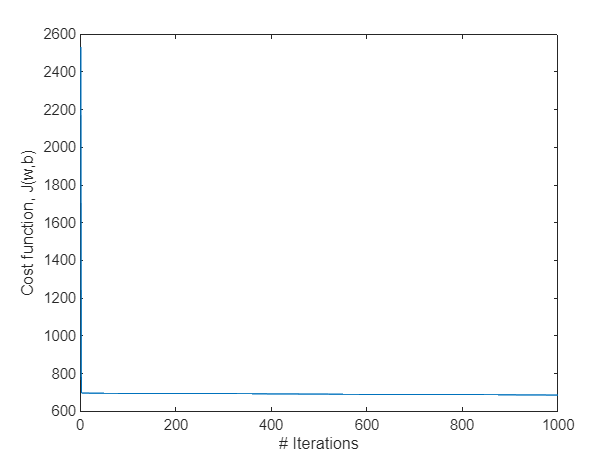

figure;
plot(1:length(J_hist),J_hist);
xlabel('# Iterations');
ylabel('Cost function, J(w,b)');

disp(['The parameters found by gradient descent: w = [',num2str(w(:,end).'),'], b = ',num2str(b(end))])

The parameters found by gradient descent: w = [0.20397   0.0037492   -0.011249   -0.065861], b = -0.0022354


for i = 1:m
    fprintf('Example #%d - Estimated value: %.2f | Target value: %.2f\n',i, w.'*X_train(i,:).'+b, y_train(i))
end

Example #1 - Estimated value: 508.04 | Target value: 409.62
Example #4.286872e+02 - Estimated value: 424.99 | Target value: 425.71
Example #4.255719e+02 - Estimated value: 425.60 | Target value: 425.59
Example #4.255964e+02 - Estimated value: 425.60 | Target value: 425.60
Example #4.255980e+02 - Estimated value: 425.60 | Target value: 425.60
Example #4.255998e+02 - Estimated value: 425.60 | Target value: 425.60
Example #4.256017e+02 - Estimated value: 425.60 | Target value: 425.60
Example #4.256035e+02 - Estimated value: 425.60 | Target value: 425.60
Example #4.256053e+02 - Estimated value: 425.61 | Target value: 425.61
Example #4.256071e+02 - Estimated value: 425.61 | Target value: 425.61
Example #4.256090e+02 - Estimated value: 425.61 | Target value: 425.61
Example #4.256108e+02 - Estimated value: 425.61 | Target value: 425.61
Example #4.256126e+02 - Estimated value: 425.61 | Target value: 425.61
Example #4.256144e+02 - Estimated value: 425.62 | Target value: 425.62
Example #4.256162

## Gradient Descent in Practice

Let's now take a look at some techniques that make gradient descent (GD) work much better (more efficient). First, let's now investigate a technique called f**eature scaling**, which will enable gradient descent to run faster.

- If we take look at the relationship between the range/magnitude/size of a feature (how big are the numbers in a feature) and range/magnitude/size of its associated parameter.

- Let's take the "prediction of house prices" problem as our example, where we will assume that we have only two features

The linear regression problem could be formulated as follows:

$\hat{p} = w_1x_1+w_2x_2 + b = \mathbf{w}^{\text{T}}\mathbf{x} + b$, where the parameter $\hat{p}$ represents the predicted price. The parameters $\mathbf{w}$, $\mathbf{x}$ and $b$ are the linear regression weights parameter, features vector and bias parameter, respectively. Note that we represent each feature corresponds to the $j^{\text{th}}$ column of the training matrix $\mathbf{X}$, where $\mathbf{x}_j = [x^{(1)}_j ~ x^{(2)}_j ~ \cdots ~ x^{(m)}_j]^\text{T}$ and $j \in \{1,2,\cdots,n\}$. 

Spefically, 

- $x_1$ represents the size of a house (square feet, range: [300-2000])

- $x_2$ is the number of bedrooms (range: [0 5]).

For this example, we can say that $x_1$ takes realtively large range of values and $x_2$ takes relatively small range of values. Now, let's take one training example:

House: $x_1 = 2000$, $x_2 = 5$, price = $500K for this training example what do you think the reasonable values for the size of the parameters $w_1$ and $w_2$? 

    1) Let's look at one set of parameters:

$w_1 = 50$, $w_2 = 0.1$, $b = 50$. In this case, the estimated price becomes, $\hat{p} = w_1x_1+w_2x_2 + b = 50*2000 + 0.1*5 + 50 = \$100,050.5\text{K}$. It is clear that the estimated price is quite far from the actual price which was $500K. This is not a good set of parameter choices for $w_1$ and $w_2$.

    2) Let's take a look at another possibility

House: 

$w_1 = 0.1$, $w_2 = 50$, $b = 50$, where the values of the weights are flipped. In this case, the estimated price becomes, $\hat{p} = w_1x_1+w_2x_2 + b = 0.1*2000 + 50*5 + 50 = \$500\text{K}
$, which is a more reasonable estimate.

- It is important to note that when a range of a feature is large ($x_1$ in this case) it is more likely that a "good model" will choose a smaller value (such as $w_1 = 0.1$). Likewise, when the range of a feature is small then a "good model" will choose a larger weight value (such as $w_2 = 50$).

### **Feature Scaling in Practice**

**Question: How does this relate to gradient descent?**

- Let's take a look at the scatter plot of the features, $x_1$and $x_2$ and contour plot.

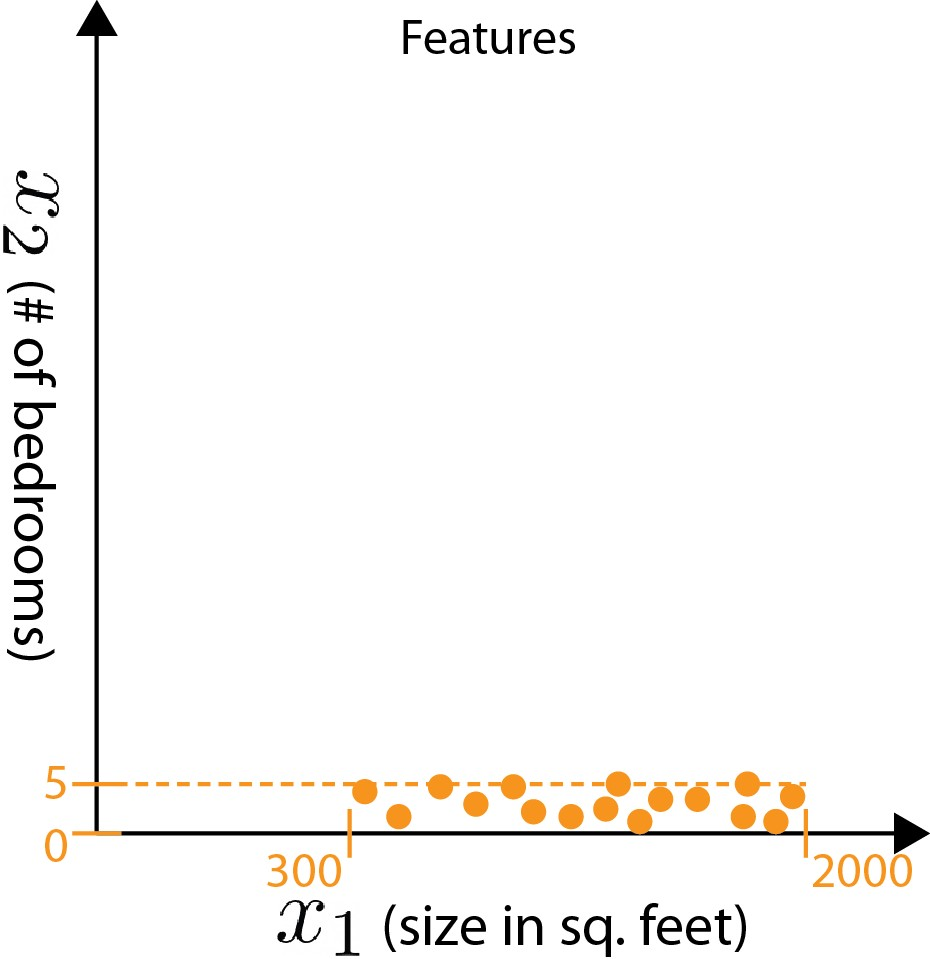

If we plot the training data, we can see that the $x_1$ is in the much larger scale/range compared to $x_2$. 

- Next, let's look how the cost function might look in the contour plot.

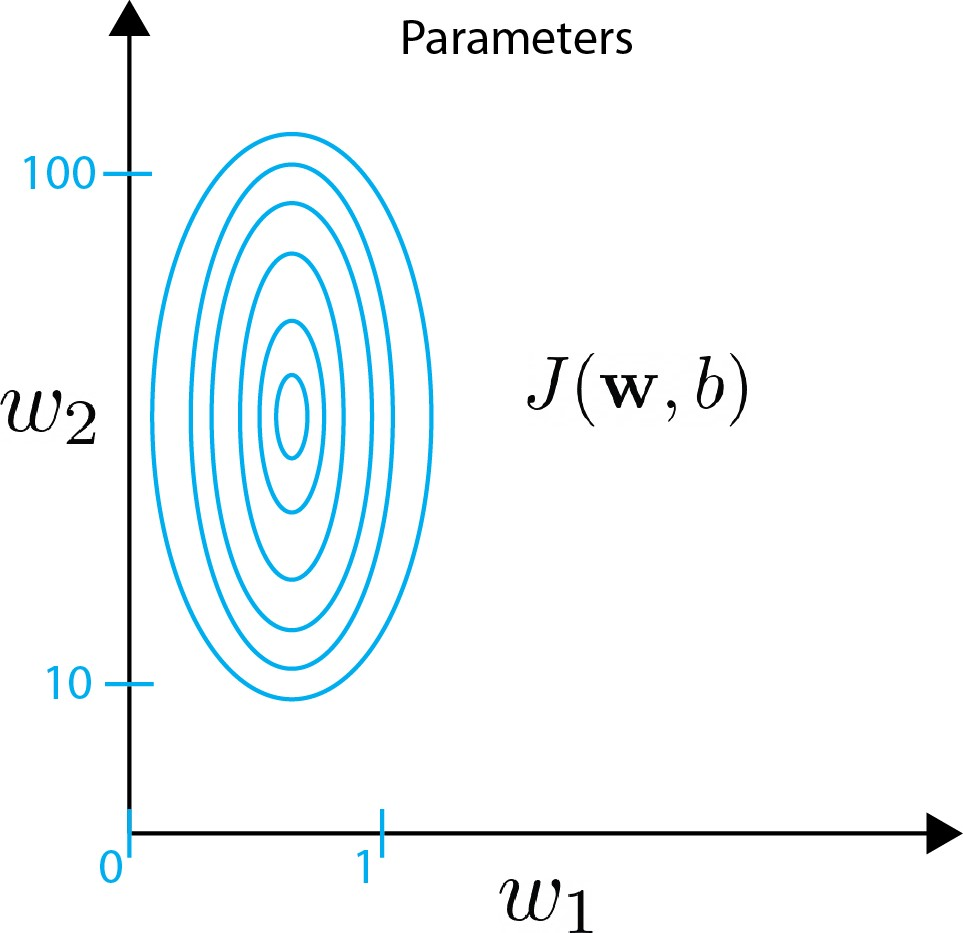

We can see that in the contour plot $w_1$ has much narrower range (say between 0 and 1) compared to $w_2$ (say between 10 and 100). Thus, the contours form ovals/ellipses as they are in shorter one side and longer in the other.

**This is because very small change in **$w_1$ **can have a very large impact on the estimated price (**$\hat{p}$**), and that corresponds to a very large impact on the cost **$J$ **as **$w_1$ **tends to be multiplied with a very large number **$x_1$** (size in sq. feet). On the contrary, it takes significantly larger change in **$w_2$ **to have a very large impact on the **$\hat{p}$ **and **$J$ **as it tends to be multiplied with a small number **$x_2$ **(# of bedrooms).**

The contour plot above is where what we will be dealing with if we decide to run the gradient descent algorithm on the example as is. As the cost function,$J(\mathbf{w},b)$, w.r.t parameters,$w_1$ and $w_2$, is tall and slim, gradient descent algorithm might be bouncing back and forth until it finds the solution, which makes the searching for the optimal point much longer and increases the possibility of divergence.

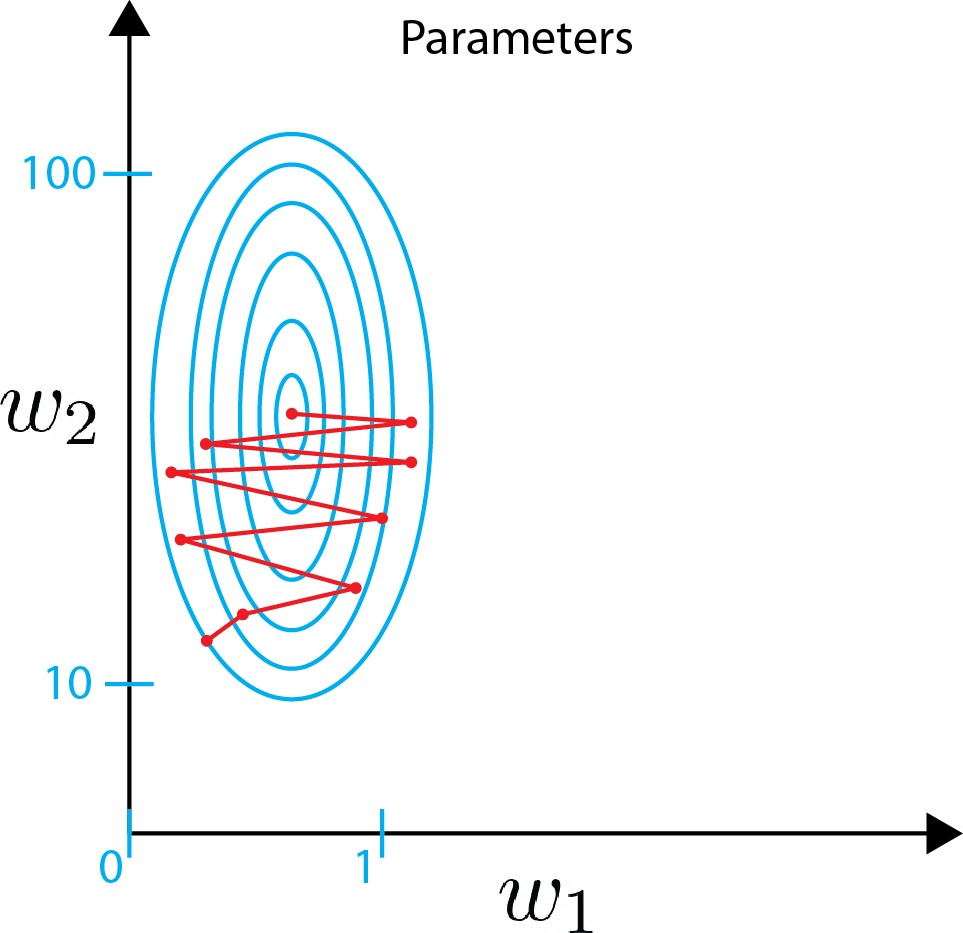

In situations like this, useful thing to do is to scale the features, this means that some transformation in the input training data is employed. Consequently, the range for the parameters $x_1$ and $x_2$ will be limited to be in 0 and 1. The corresponding data points and cost function plot after the feature scaling becomes,

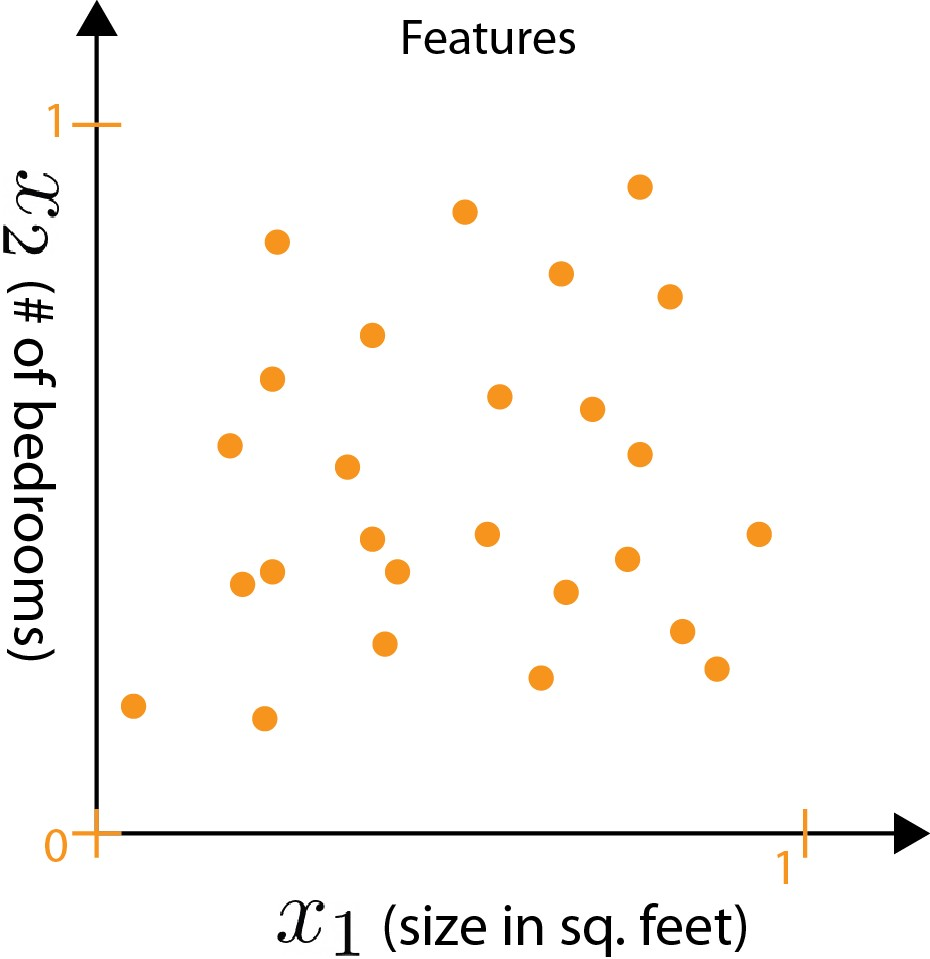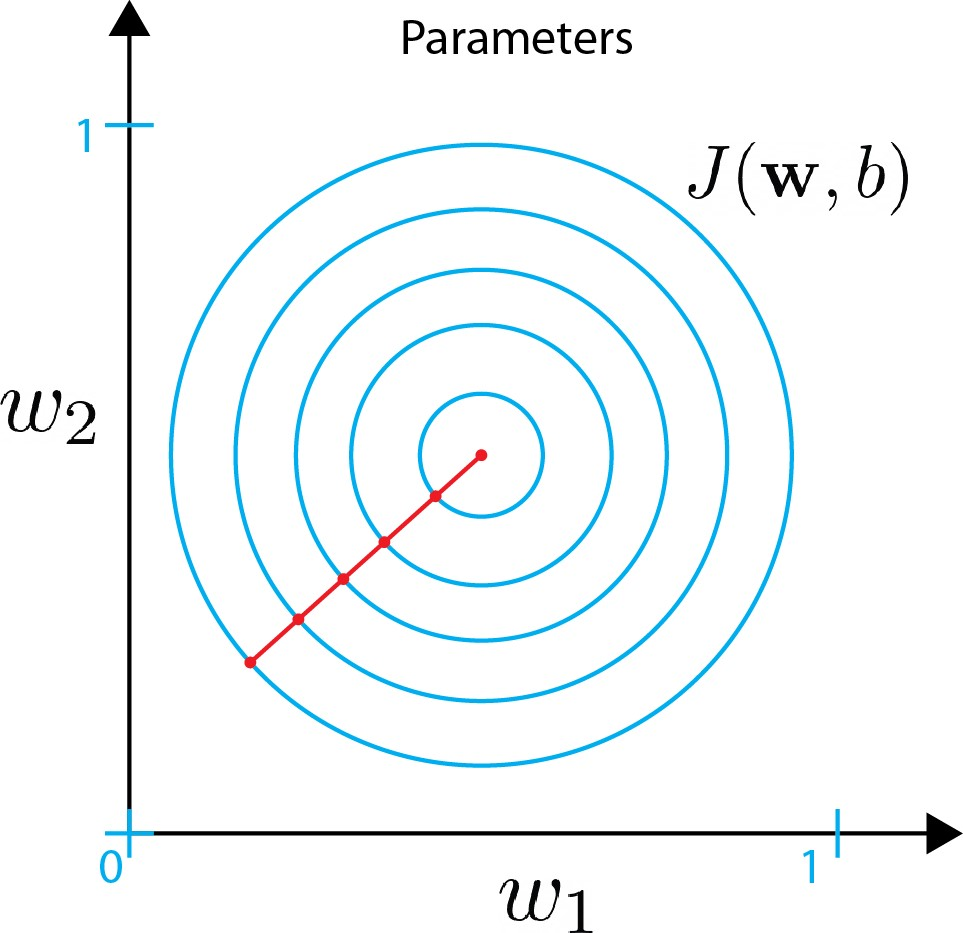

Please note from the transformed data yields a contour plot that is more uniform and symmetrical (shapes more like circles). As a result, gradient descent can find a much more direct path to the global minimum compared to the tall and slim cost function in untransformed training data.

Recap: When you have different features with different range of values, it can cause the gradient descent algorithm to operate slowly. Rescaling the features into a comparable scale makes gradient descent run much faster. 

Question: Why do we need feature scaling?

- It makes gradient descent algorithm operates faster

- It prevents the optimization from getting stuck in local optima

- It gives a better error/cost surface shape

- Machine learning algorithms just see numbers and doesn't know what the numbers represent — if there is a vast difference in the range say few ranging in thousands and few ranging in the tens, and the model might make the underlying assumption that higher ranging numbers have superiority of some sort. Thus, these more significant numbers start playing a more decisive role while training the model. 

For instance,

Normally, weight cannot be compared with price as it won't yield any meaningful result, however, because of the large numbers in the weight column algorithm might assume that the weight is more important feature than the price. However, if we convert the weights to kg, then price becomes the more important feature.

To avoid that, we can employ feature scaling, where one significant number doesn’t impact the model just because of their large magnitude.

**Question: But how do we actually rescale features into a comparable scale?**

If we look at the data below, where the features $x_1$ (room size in sq. feet) and $x_2$ (number of bedrooms) is in the range of $[300 ~~~ 2000]$ and $[0 ~~~ 5]$, respectively.

**1) Maximum value scaling:** One way to scale is to take each $x_1$ and $x_2$ value is to divide them into the maximum value that each feature could reach,

 
$$\hat{\mathbf{x}}_j = \frac{\mathbf{x}_j}{\max\{ \mathbf{x}_j \}}$$


where $i \in \{ 1,2,\cdots, m \}$ and $j \in \{ 1,2,\cdots,n \}$. Thus, the scaled $x_1$ and $x_2$ will be in the range of $[0.15 ~~~ 1]$ and $[0 ~~~ 1]$, respectively.

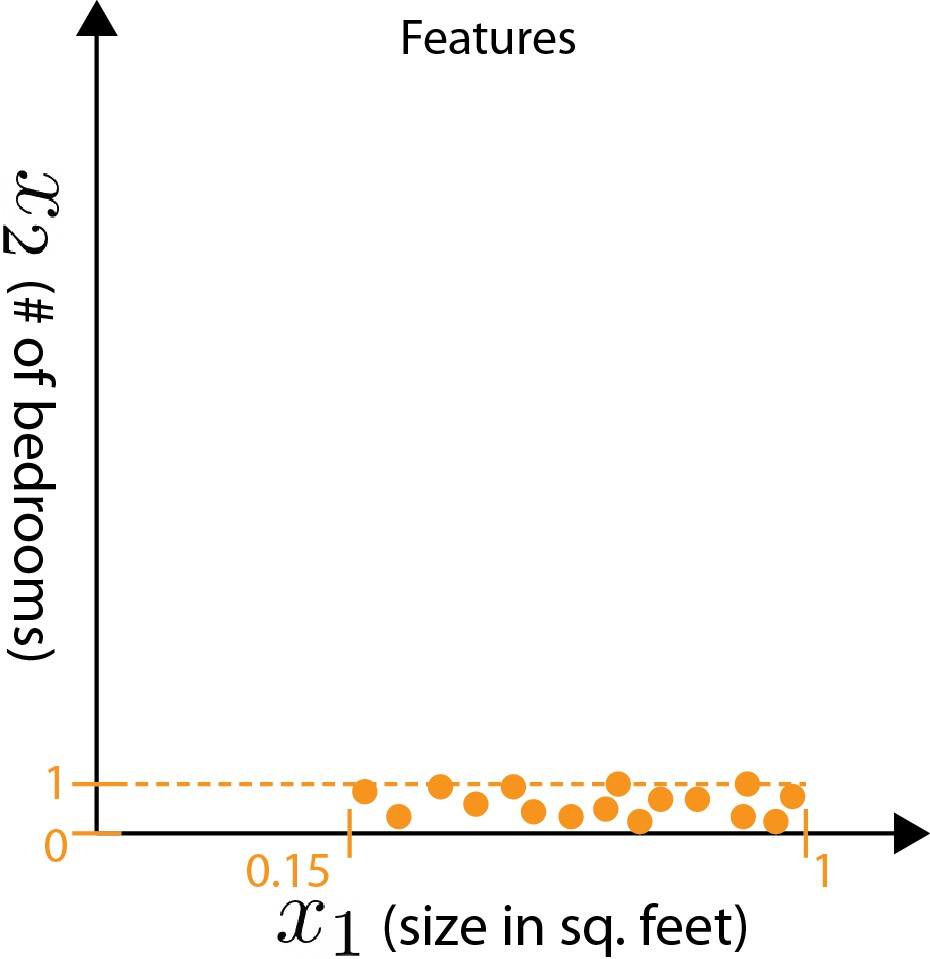

**2) Min-max scaling:** Min-max scaling is one of the simplest methods to rescaling features into the interval $[a ~~~ b]$ in its generalized form. To implement the min-max scaling we need the following operation.


$$\hat{\mathbf{x}}_j = \frac{ \mathbf{x}_j- \min \{\mathbf{x}_j\} }{ \max \{\mathbf{x}_j\} -  \min \{\mathbf{x}_j\} }(b-a)  + a$$


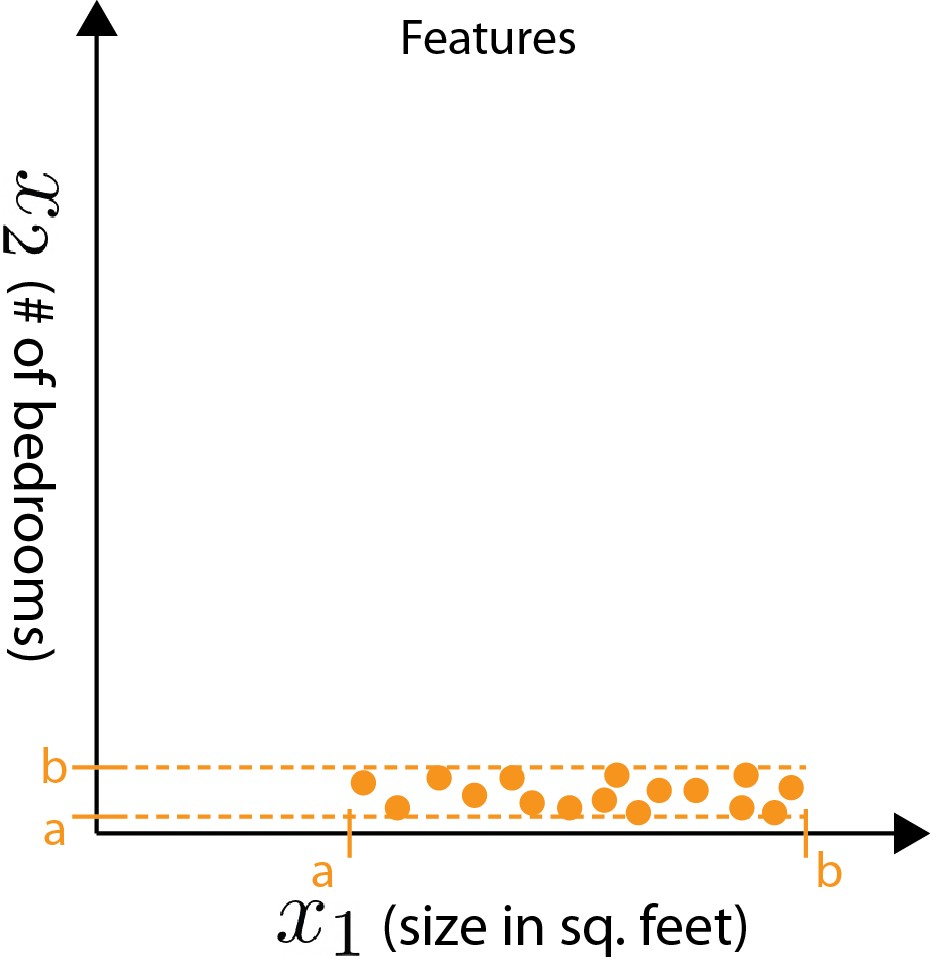

**3) Mean value scaling:** Similar to the min-max scaling, you can also use the mean value for scaling the feature vector, which is called "mean normalization". Mean normalization rescales the datapoints in a way that they are symmetrically scattered around the origin,


$$\hat{\mathbf{x}}_j = \frac{\mathbf{x}_j -\mu_{\mathbf{x}_j}}{\max\{\mathbf{x}_j\}-\min\{\mathbf{x}_j\}}$$


where $i \in \{ 1,2,\cdots, m \}$ and $j \in \{ 1,2,\cdots,n \}$. The mean value of the each feature could be calculated as $\mu_j = \text{E}\{ x_j \}$. If we assume that the mean value $x_1$ is $\mu_1=600$, then the $x_1$ will be in the range of $[-0.18 ~~~ 0.82]$. Similarly, if the mean value of the feature $x_2$ is $\mu_2=2.3$, the $x_2$ will be in the range of $[-0.46 ~~~ 0.54]$.

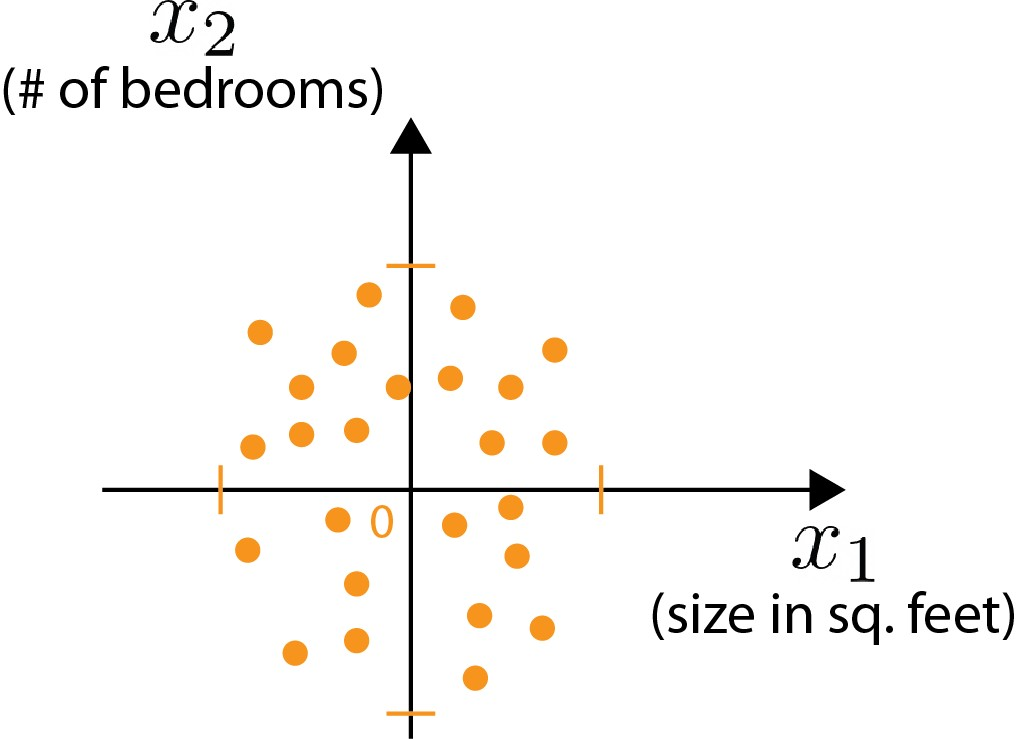

**4) Z-score normalization:** There is one last normalization method called z-score normalization, which utilizes mean and standard deviation, to standardize each feature (with the assumption of each feature is Gaussian distributed), $\hat{\mathbf{x}}_j = \frac{\mathbf{x}_j-\mu_{\mathbf{x}_j}}{\sigma_{\mathbf{x}_j}}$, where $\mu_{\mathbf{x}_j} = \text{E}\{ \mathbf{x}_j \}$, $\sigma^2_j = \text{E}\{ (\mathbf{x}_j-\mu_{\mathbf{x}_j})^2 \}$ and $i \in \{ 1,2,\cdots, m \}$ and $j \in \{ 1,2,\cdots,n \}$. For the feature $x_1$ with the mean and stadard deviation of $\mu_1 = 600$ and $\sigma_1 = 450$, the range of the $x_1$ becomes $[-0,67 ~~~ 3.1]$. Similarly, for the feature $x_2$ with the mean and stadard deviation of $\mu_2 = 2.3$ and $\sigma_2 = 1.4$, the range of the $x_2$ becomes $[-1.6 ~~~ 1.9]$.

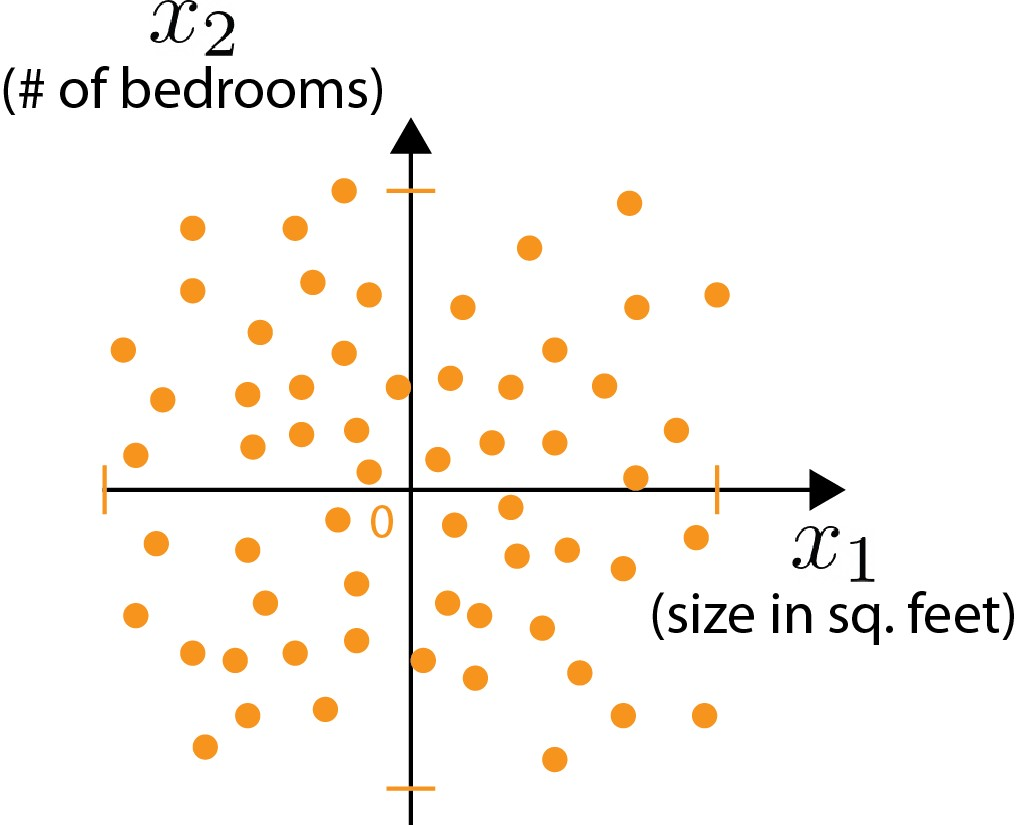

As a rule of thumb in feature scaling, aim for about $-1 \leq x_j \leq 1$ for each feature $x_j$. These -1 and 1 values could be a little bit loose depending on the dataset and the application. For example,

- $-1 \leq x_j \leq 1$, $-3 \leq x_j \leq 3$, $-0.3 \leq x_j \leq 0.3$ $\Longrightarrow$ Acceptable range

- $0 \leq x_j \leq 3$ $\Longrightarrow$ OK, no scaling needed

- $-2 \leq x_j \leq 0.5$$\Longrightarrow$ OK, no scaling needed

- $-100 \leq x_j \leq 100$$\Longrightarrow$ Too large, scaling needed

- $-0.001 \leq x_j \leq 0.001$$\Longrightarrow$ Too small, scaling needed

- $98.6 \leq x_j \leq 105$$\Longrightarrow$ Too large, scaling needed

**Question: With feature scaling, how are we going to know that the gradient descent algorithm finds the global minimum (converging)?**

When running gradient descent, how can we be sure that it is converging (the algortihm is getting closer and closer to the global minimum of the cost function)? One of the key choices in gradient descent algorithm,

- 
$$w_j =  w_j - \alpha\frac{1}{m}\sum_{i=1}^{m} \left( \mathbf{w}^{\text{T}}\mathbf{x}^{(i)} +b - y^{(i)} \right) \cdot
x_j^{(i)}$$


- $b = b - \alpha\frac{1}{m} \sum_{i=1}^{m} \left( \mathbf{w}^{\text{T}}\mathbf{x}^{(i)} \right) + b - y^{(i)}$, where $i \in \{ 1,2,\cdots,m\}$ and $j \in \{ 1,2,\cdots, n\}$

is the correct selection of the learning rate ($\alpha$). Recall that the main objective of the gradient algorithm is: $\min_{\mathbf{w},b}J(\mathbf{w},b)$. Therefore, if we plot the cost function ($J$) w.r.t the number of iterations, where each iteration means after the simultaneous updates of the parameters $\mathbf{w}$ and $b$.

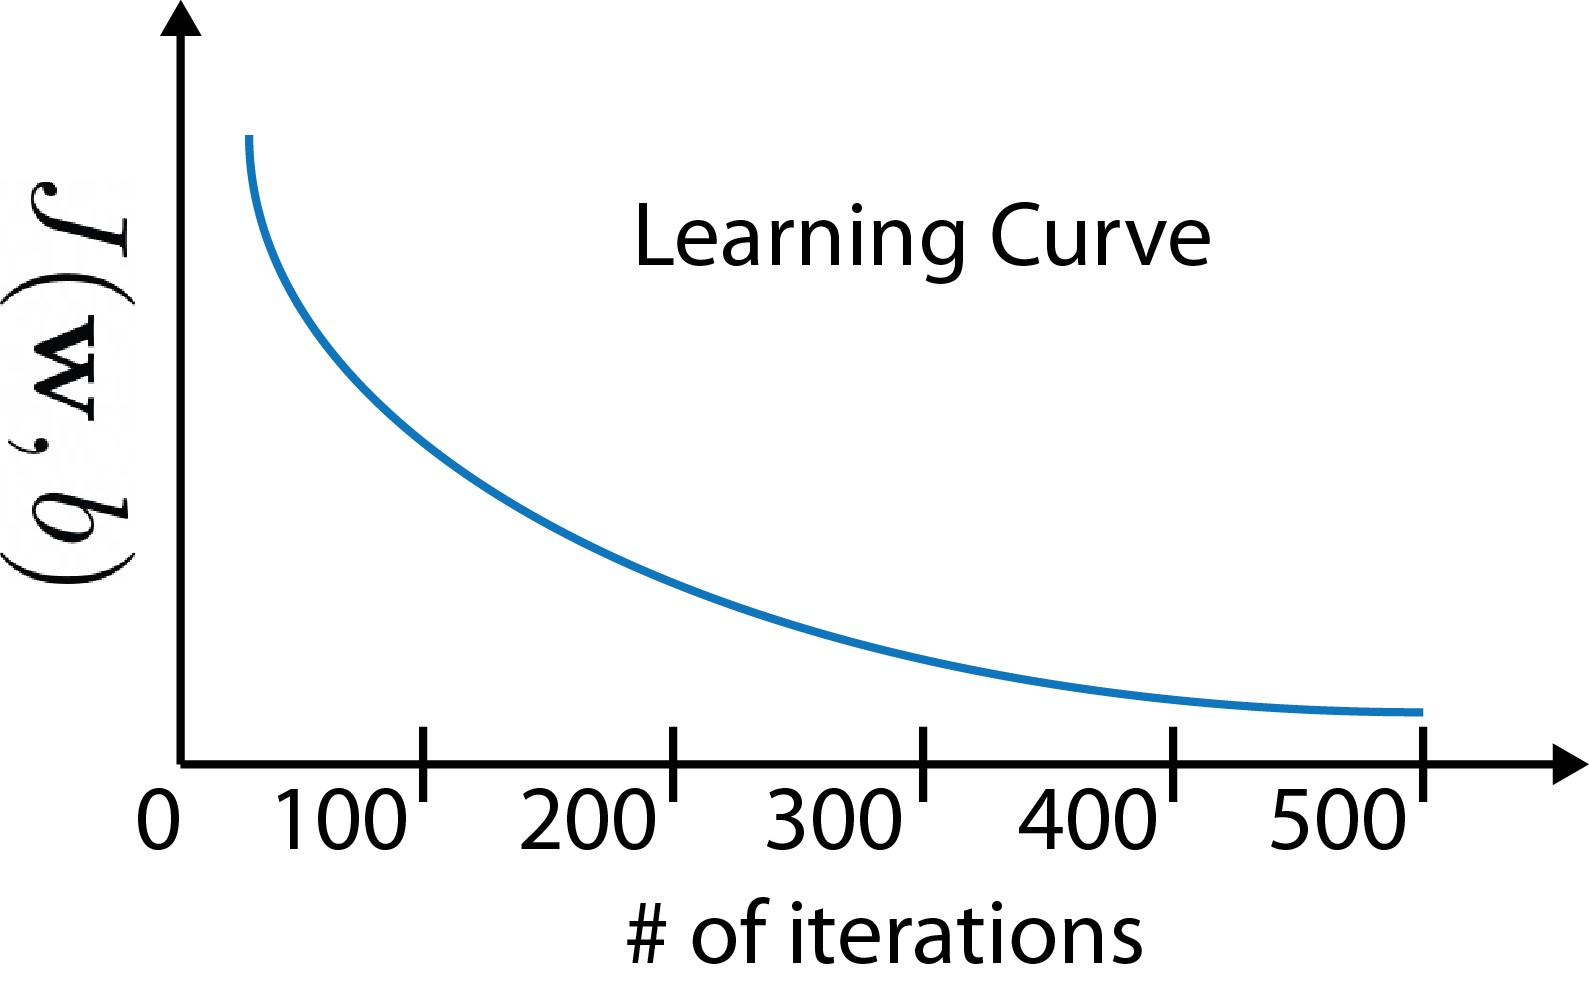

This figure is called the **learning curve**. If the gradient descent is working properly, the cost ($J$) should **decrease** after every iteration. If $J$**ever** increases from one iteration to other, that might mean that either $\alpha$ is chosen poorly (usually means that $\alpha$ is too large) or there might be a potential bug in the code. It is also important to note that the cost ($J$) is not decreasing much between the iterations 400 and 500, this means that the gradient descent is more or less **converged**.

Another way to decide whether your model is done training or not is the **automatic convergence test**,

- Let $\epsilon$ be $10^{-3}$

- If $J(\mathbf{w},b)$ decreases by $\leq \epsilon$ in one iteration, **declare convergence** (hopefully found parameters $\mathbf{w}$ and $b$ to be close to the global minimum).

**Let's now learn about how to choose an appropriate learning rate.**

The gradient descent based learning algorithm will run much better with the selection of the appropriate learning rate. If it is too small, it might converge but run very slowly. However, if it is too large it might not even converge. It is important to note that with a small enough $\alpha$, the cost function $J(\mathbf{w},b)$ should **decrease** on every iteration. If we set learning rate to be a very small value and still the cost function increases over number of iterations, it is a strong indicator of an implementation bug. 

- As a rule of thumb. values of learning rate to try: $\alpha \in \{ 0.001,0.003,0.01,0.03,0.1,0.3, 1\}$, where each item is roughly 3 times larger than the previous one.

Let's have a practice to understand the concepts explanied above!

The goal of the practice is as follows:

- Explore the impact of learning rate on the gradient descent (GD) performance.

- Explore the impact of feature scaling on the GD performance.

Similar to the previous practices, we will use the housing price prediction dataset.

% Load House Prices Dataset
dataset = importdata('house_prices_dataset.txt');
X_train = dataset(:,1:4);
y_train = dataset(:,end);
disp(['Size X_train: [' num2str(size(X_train)) ']'])

Size X_train: [99   4]


disp(['Size y_train: [' num2str(size(y_train)) ']'])

Size y_train: [99   1]


X_train

X_train =         1244           3           1          64
        1947           3           2          17
        1725           3           2          42
        1959           3           2          15
        1314           2           1          14
         864           2           1          66
        1836           3           1          17
        1026           3           1          43
        3194           4           2          87
         788           2           1          80


Let's visualize the dataset and its features by plotting each feature against the price

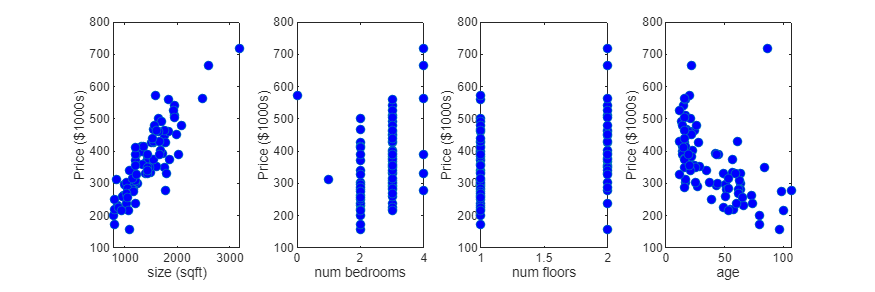

plotDatasetAgainstFeatures(X_train,y_train,["size (sqft)","num bedrooms","num floors","age"],"Price ($1000s)")

Plotting the dataset features w.r.t. the targets gives us some hint of which features play a significant role on price. For instance, number of bedrooms and floors don't have a strong impact on price. However, we can infer that larger and newer houses have higher prices compared to smaller and older houses.

Let's display and compare the peak-to-peak range between the original and z-score normalized data

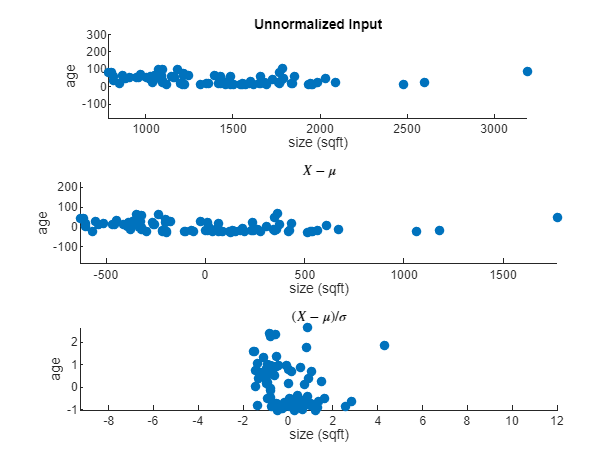

mu = mean(X_train);
sigma = std(X_train);
X_mean = X_train - mu;
X_norm = (X_train-mu)./sigma;

figure;
tiledlayout(3,1,"TileSpacing","loose")

nexttile
scatter(X_train(:,1),X_train(:,4),'MarkerFaceColor','flat')
title("Unnormalized Input")
xlabel("size (sqft)")
ylabel("age")
axis equal

nexttile
scatter(X_mean(:,1),X_mean(:,4),'MarkerFaceColor','flat')
title("$X-\mu$","Interpreter","latex")
xlabel("size (sqft)")
ylabel("age")
axis equal

nexttile
scatter(X_norm(:,1),X_norm(:,4),'MarkerFaceColor','flat')
title("$(X-\mu)/\sigma$","Interpreter","latex")
xlabel("size (sqft)")
ylabel("age")
axis equal


disp(['Peak-to-peak range of each column (original): [' num2str(max(X_train) - min(X_train)) ']'])

Peak-to-peak range of each column (original): [2406     4     1    95]


disp(['Peak-to-peak range of each column (normalized): [' num2str(max(X_norm) - min(X_norm)) ']'])

Peak-to-peak range of each column (normalized): [5.8157      6.1042      2.0459      3.6667]


 Let's visualize the distribution of some features before and after the normalization

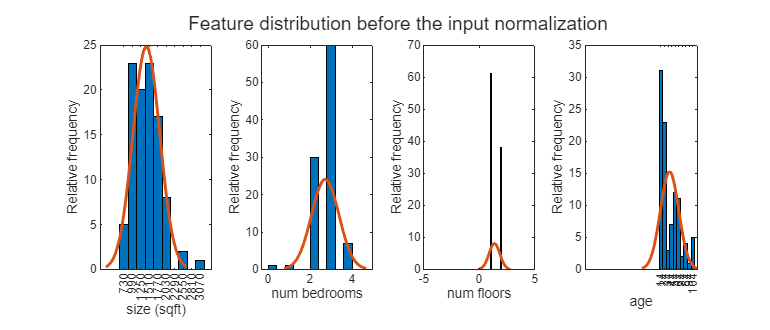

featureLabels = ["size (sqft)","num bedrooms","num floors","age"];
f = figure;
T = tiledlayout(1,length(featureLabels));
for i = 1:length(featureLabels)
    nexttile
    h = histfit(X_train(:,i));
    xlabel(featureLabels(i))
    ylabel("Relative frequency")
end
title(T,"Feature distribution before the input normalization")
f.Position = [0 0 700 300];

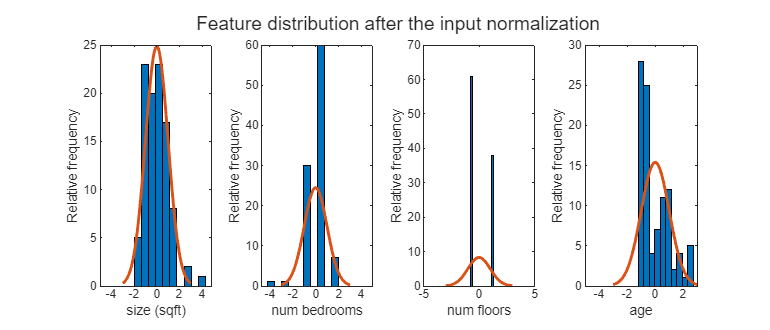

f = figure;
T = tiledlayout(1,length(featureLabels));
for i = 1:length(featureLabels)
    nexttile
    h = histfit(X_norm(:,i));
    xlabel(featureLabels(i))
    ylabel("Relative frequency")
end
title(T,"Feature distribution after the input normalization")
f.Position = [0 0 700 300];

It is important to note from above figures that the all the features are centered around 0 and they also share the same range which is roughly [-2 2]. Let's run our gradient descent algorithm with the normalized input and significantly larger lerning rate to see the input normalization effect.

% BGD settings
alpha = 1.0e-1; % Learning rate
condStop = 1e-3; % Stopping condition
maxIter = 1000; % Maximum number of iterations
verbose = false;
verboseFreq = 100;

% Run BGD algoritm and print the results
 
tStart = tic;
[w_vec,b_vec,J_hist] = hBatchGradientDescentMV(X_norm, y_train, alpha, condStop, ...
                                                maxIter, verbose, verboseFreq);

BGD Stopped: max number of iterations (999)


tElapsed2 = toc(tStart);

As can be seen from the results the normalized inputs yield a faster execution time

disp(['Elapsed time unnormalized input: ' num2str(tElapsed1)])

Elapsed time unnormalized input: 0.19128


disp(['Elapsed time normalized input: ' num2str(tElapsed2)])

Elapsed time normalized input: 0.050034


Let's plot the cost function $J(\mathbf{w},b) = \frac{1}{2m}\sum_{i=1}^{m} \left( \mathbf{w}^{\text{T}} \mathbf{x}^{(i)}+b - y^{(i)} \right)^2 = \frac{1}{2m}\sum_{i=1}^{m} \left( \mathbf{x}^{(i)}\mathbf{w} +b - y^{(i)} \right)^2$ contour plot for the unnormalized and normalized features.

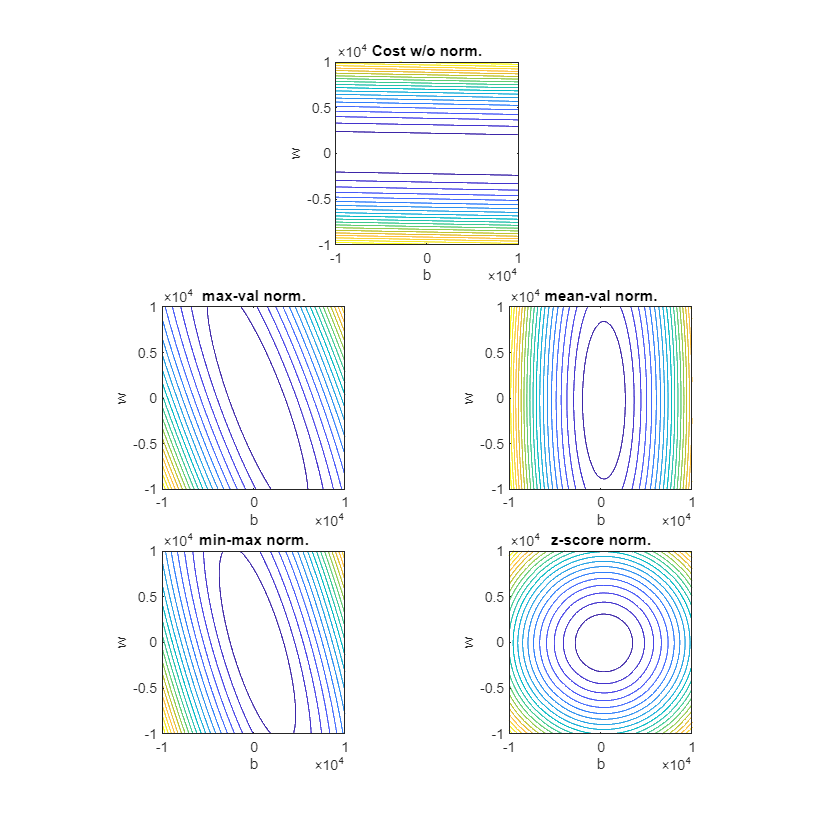

f = figure;
tiledlayout(3,2,"TileSpacing","tight");
X = X_train(:,4); % Input data
y = y_train;

% Plot the cost function without input normalization
w_vec = -1e4:50:1e4; % weights vector
b_vec = -1e4:50:1e4; % bias vector

% Plot the cost function before the input normalization
J = scanCostFunction(w_vec,b_vec,X,y);

nexttile([1 2]);
contour(b_vec,w_vec,J,20);
xlabel('b')
ylabel('w')
title("Cost w/o norm.")
axis equal

%------------------------------------------------------------
% Max-value normalize the input feature
X_normalize = normalizeInput(X,"Max Value");

% Plot the cost function after input normalization
J_maxVal = scanCostFunction(w_vec,b_vec,X_normalize,y);

nexttile;
contour(b_vec,w_vec,J_maxVal,20);
xlabel('b')
ylabel('w')
title("max-val norm.")
axis equal

%------------------------------------------------------------
% Mean-value normalize the input feature
X_normalize = normalizeInput(X,"Mean Value");

% Plot the cost function after input normalization
J_meanVal = scanCostFunction(w_vec,b_vec,X_normalize,y);

nexttile;
contour(b_vec,w_vec,J_meanVal,20);
xlabel('b')
ylabel('w')
title("mean-val norm.")
axis equal

%------------------------------------------------------------
% Min-max normalize the input feature
X_normalize = normalizeInput(X,"Min-max");

% Plot the cost function after input normalization
J_minMax = scanCostFunction(w_vec,b_vec,X_normalize,y);

nexttile;
contour(b_vec,w_vec,J_minMax,20);
xlabel('b')
ylabel('w')
title("min-max norm.")
axis equal

%------------------------------------------------------------
% z-score normalize the input feature
X_normalize = normalizeInput(X,"z-score");

% Plot the cost function after input normalization
J_zScore = scanCostFunction(w_vec,b_vec,X_normalize,y);

nexttile;
contour(b_vec,w_vec,J_zScore,20);
xlabel('b')
ylabel('w')
title("z-score norm.")
axis equal
f.Position = [0 0 750 750];

Let's plot two features $w_1$ and $w_2$ w.r.t the cost function ($J(\mathbf{w},b) = \frac{1}{2m}\sum_{i=1}^{m} \left( \mathbf{x}^{(i)}\mathbf{w} +b - y^{(i)} \right)^2$)

% Run BGD algoritm and print the results
 

[w_vec,b_vec,J_hist] = hBatchGradientDescentMV(X_norm,y_train,alpha,condStop,maxIter,verbose,verboseFreq);

BGD Stopped: max number of iterations (999)


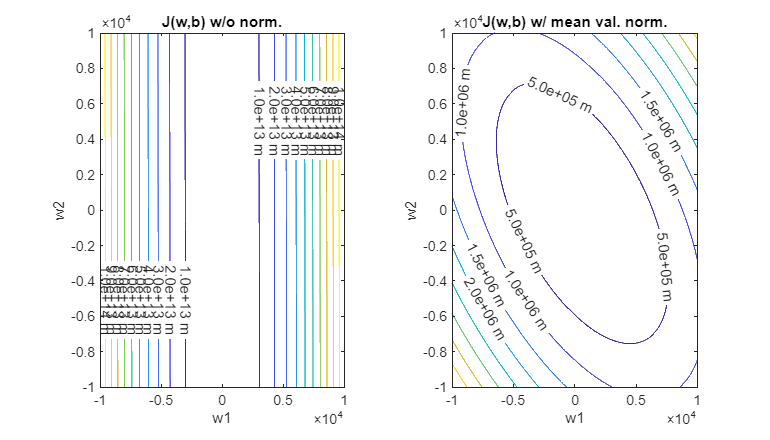

f = figure;
T = tiledlayout(1,2,"TileSpacing","loose");

% Cost function without normalization
w1_vec = -1e4:10:1e4; % w1 vector
w2_vec = -1e4:10:1e4; % w2 vector
X_trainSub = [X_train(:,1) X_train(:,2)]; % two out of four features (subset)
J = [];
for i = 1:length(w1_vec)
     w1 = w1_vec(i);
    for j = 1:length(w2_vec)
        w2 = w2_vec(j);
        w_subVec = [w1 w2];

        J(i,j) = ( 1/(2*length(X_trainSub)) )*sum( ((w_subVec*X_trainSub.')+b_vec(end)-y_train.').^2 );
    end
end

nexttile
contour(w1_vec,w2_vec,J.',"ShowText",true,"LabelFormat","%0.1e m")
xlabel("w1")
ylabel("w2")
title("J(w,b) w/o norm.")

% Cost function with normalization
w1_vec = -1e4:10:1e4; % w1 vector
w2_vec = -1e4:10:1e4; % w2 vector
X_norm = [normalizeInput(X_train(:,1),"Mean Value") normalizeInput(X_train(:,2),"Mean Value")];
J = [];
for i = 1:length(w1_vec)
     w1 = w1_vec(i);
    for j = 1:length(w2_vec)
        w2 = w2_vec(j);
        w_subVec = [w1 w2];

        J(i,j) = ( 1/(2*length(X_norm)) )*sum( ((w_subVec*X_norm.')+b_vec(end)-y_train.').^2 );
    end
end

nexttile
contour(w1_vec,w2_vec,J.',"ShowText",true,"LabelFormat","%0.1e m")
xlabel("w1")
ylabel("w2")
title("J(w,b) w/ mean val. norm.")
f.Position = [0 0 700 400];

### Learning Rate in Practice

We know that the learning rate ($\alpha$) controls the size of the update in each iteration and it is shared by all the parameters. Let's run gradient descent and try a few settings.

#### Case 1: alpha = 9.9e-7

% BGD settings
alpha = 9.9e-7; % Learning rate
condStop = 1e-3; % Stopping condition
maxIter = 1e4; % Maximum number of iterations
verbose = false;
verboseFreq = 100;

% Run BGD algoritm and print the results
 
[w_hist,b_hist,J_hist] = hBatchGradientDescentMV(X_train,y_train,alpha,condStop,maxIter,verbose,verboseFreq);

BGD Stopped: max number of iterations (9999)


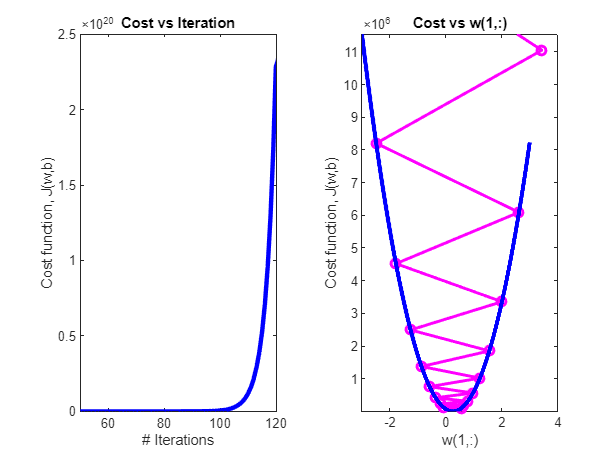

w_vec = -3:0.001:3; % weights vector
b_vec = 0; % bias vector

% Plot the cost function
J = scanCostFunction(w_vec,b_vec,X_train(:,1),y_train);

figure;
tiledlayout(1,2,"TileSpacing","loose")

nexttile
plot(1:length(J_hist),J_hist,'b','LineWidth',3);
xlabel("# Iterations");
ylabel("Cost function, J(w,b)");
title("Cost vs Iteration")
xlim([50 120])

nexttile
plot(w_hist(1,:),J_hist,'mo-','LineWidth',2)
hold on
plot(w_vec,J,'b','LineWidth',3)
hold off
title("Cost vs w(1,:)")
xlabel("w(1,:)");
ylabel("Cost function, J(w,b)");
ylim([min(J) max(J)])

It appears the learning rate is too high. The solution does not converge. Cost is *increasing* rather than decreasing. 

#### Case 2: alpha = 9e-7

% BGD settings
alpha = 9e-7; % Learning rate
condStop = 1e-3; % Stopping condition
maxIter = 1e4; % Maximum number of iterations
verbose = false;
verboseFreq = 100;

% Run BGD algoritm and print the results
 
[w_hist,b_hist,J_hist] = hBatchGradientDescentMV(X_train,y_train,alpha,condStop,maxIter,verbose,verboseFreq);

BGD Stopped: max number of iterations (9999)


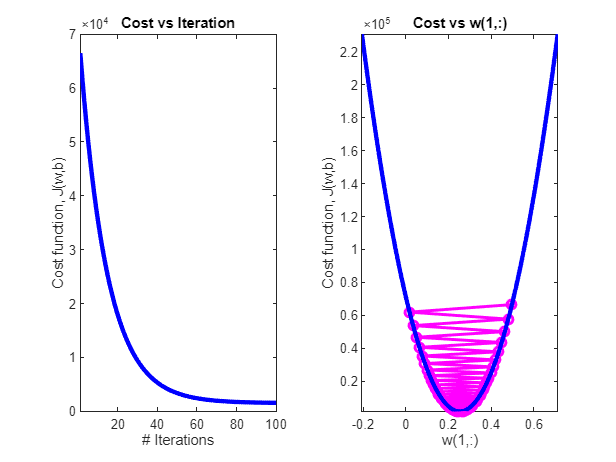

w_vec = -3:0.001:3; % weights vector
b_vec = 0; % bias vector

% Plot the cost function
J = scanCostFunction(w_vec,b_vec,X_train(:,1),y_train);

figure;
tiledlayout(1,2,"TileSpacing","loose")

nexttile
plot(1:length(J_hist),J_hist,'b','LineWidth',3);
xlabel("# Iterations");
ylabel("Cost function, J(w,b)");
title("Cost vs Iteration")
xlim([1 100])

nexttile
plot(w_hist(1,:),J_hist,'mo-','LineWidth',2)
hold on
plot(w_vec,J,'b','LineWidth',3)
hold off
title("Cost vs w(1,:)")
xlabel("w(1,:)");
ylabel("Cost function, J(w,b)");
ylim([min(J) max(J)/50])

Cost is decreasing throughout the run showing that alpha is not too large.

#### Case 2: alpha = 1e-7

% BGD settings
alpha = 1e-7; % Learning rate
condStop = 1e-3; % Stopping condition
maxIter = 1e4; % Maximum number of iterations
verbose = false;
verboseFreq = 100;

% Run BGD algoritm and print the results
 
[w_hist,b_hist,J_hist] = hBatchGradientDescentMV(X_train,y_train,alpha,condStop,maxIter,verbose,verboseFreq);

BGD Stopped: max number of iterations (9999)


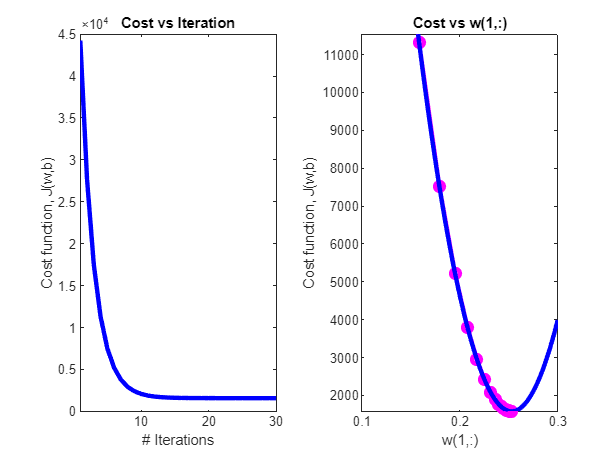

w_vec = -3:0.001:3; % weights vector
b_vec = 0; % bias vector

% Plot the cost function
J = scanCostFunction(w_vec,b_vec,X_train(:,1),y_train);

figure;
tiledlayout(1,2,"TileSpacing","loose")

nexttile
plot(1:length(J_hist),J_hist,'b','LineWidth',3);
xlabel("# Iterations");
ylabel("Cost function, J(w,b)");
title("Cost vs Iteration")
xlim([1 30])

nexttile
plot(w_hist(1,:),J_hist,'mo-','LineWidth',3)
hold on
plot(w_vec,J,'b','LineWidth',3)
hold off
title("Cost vs w(1,:)")
xlabel("w(1,:)");
ylabel("Cost function, J(w,b)");
ylim([min(J) max(J)/1000])
xlim([0.1 0.3])

You can see from the figures that $w_1$ is decreasing without crossing the minimum. This solution will also converge, though not quite as quickly as the previous example.

## Local Function Definitions

function plotDatasetAgainstFeatures(X_train,y_train,Xstring,ystring)

% Validity checks
if size(X_train,2) ~= numel(Xstring)
    error("Training data and respective string sizes are not matching.")
end
if size(y_train,2) ~= numel(ystring)
    error("Targets and respective strings vector sizes are not matching.")
end

% Create the feature plots
f = figure;
T = tiledlayout(1,size(X_train,2),"TileSpacing","loose");

for i = 1:size(X_train,2)
    nexttile
    plot(X_train(:,i),y_train,'o','MarkerFaceColor','b')
    xlabel(Xstring(i));
    ylabel(ystring)
end
f.Position = [0 0 900 300];
end

function normInput = normalizeInput(input,normType)
if strcmpi(normType,"Max Value")
    normInput = input./max(input);
elseif strcmpi(normType,"Min-max")
    a = 0;
    b = 1;
    normInput = ( (input - min(input))/(max(input)-min(input)) )*(b-a) + a;
elseif strcmpi(normType,"Mean Value")
    meanInput = (1/length(input))*sum(input);
    normInput = ( (input - meanInput)/(max(input)-min(input)) );
elseif strcmpi(normType,"z-score")
    meanInput = (1/length(input))*sum(input);
    varInput = (1/(length(input)-1))*sum((input-meanInput).^2); % sample variance (N-1)
    normInput = (input - meanInput)/sqrt(varInput);
else
    error("Undefined input normalization type.")
end

end

function J = scanCostFunction(w_vec,b_vec,X,y)
% Calculate the cost function values
J = [];

for i = 1:length(w_vec)
    w = w_vec(i);
    for j = 1:length(b_vec)
        b = b_vec(j);
        J(i,j) = (1/(2*length(X))).*sum((w.*X+b-y).^2);
    end
end

end